
R_0 = [0;0;0];
V_0 = [0;0;0];
t = linspace(0,10,101)

t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


A = [0;0;1];
V = A*t + V_0;

R = R_0 + V.* t + 0.5 * A .*t.^2

R =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

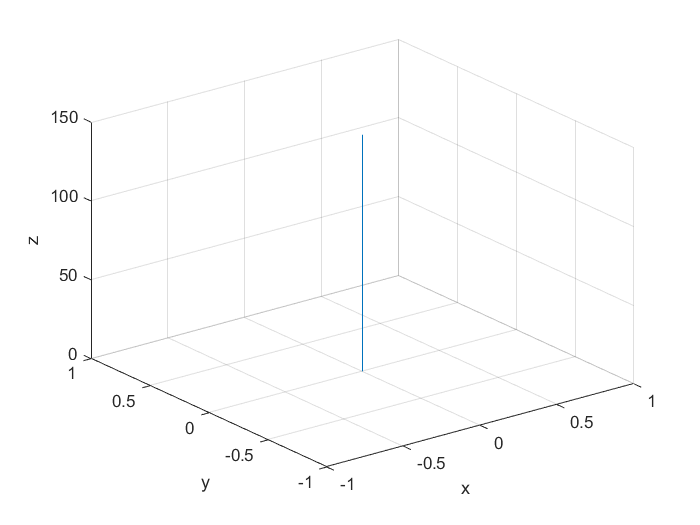

figure
plot3(R(1,:),R(2,:),R(3,:))
xlabel('x')
ylabel("y")
zlabel("z")
grid on;

test

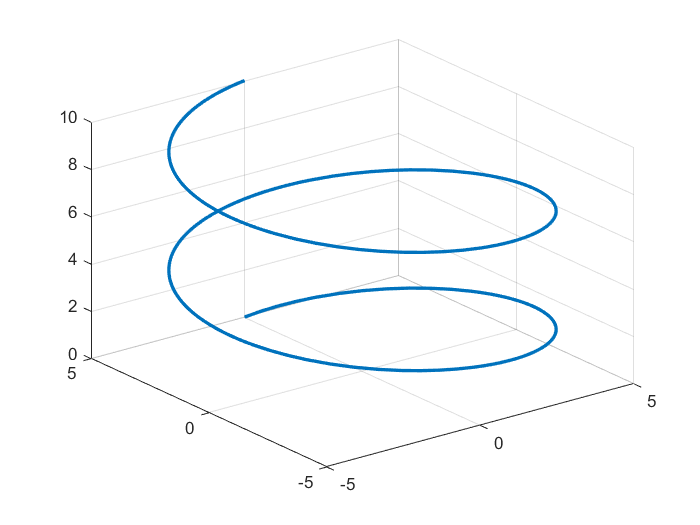

dia = 10;
pitch = 5;
height = 10;
syms t
radius = dia/2;
x = radius*sin(t);
y = radius*cos(t);
z = t/(2*pi)*pitch;
tmax = 2*pi*height/pitch;
fplot3(x, y, z, [0 tmax], 'LineWidth', 2)

spirale:

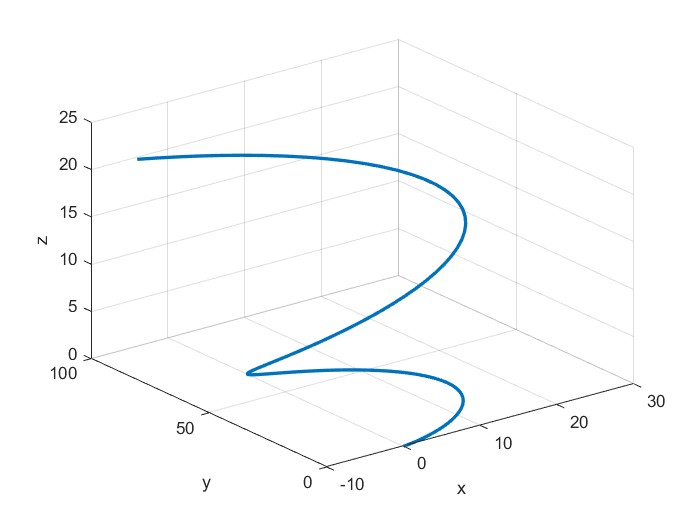

R_0 = [0; 0; 0];
V_0 = [0; 0; 0];
t = linspace(0, 10, 101);
A = [5 * cos(t); 5 * sin(t); 0.2 * ones(size(t))]; % Erhöhte Beschleunigung
V = cumtrapz(t, A, 2) + V_0;

R = R_0 + cumtrapz(t, V, 2) + 0.5 * cumtrapz(t, A, 2) .* t;
figure;
plot3(R(1,:), R(2,:), R(3,:), 'LineWidth', 2);
xlabel('x');
ylabel('y');
zlabel('z');
grid on;

In diesem aktualisierten Code wird die Beschleunigung `A` so geändert, dass sie sich mit der Zeit ändert und eine spiralförmige Bahn erzeugt. Hier wird `A` als ein Vektor verwendet, der die x-Komponente als `cos(t)`, die y-Komponente als `sin(t)` und die z-Komponente als konstant 1 enthält. Dadurch ändert sich die Richtung der Beschleunigung über die Zeit und erzeugt eine Spirale.

Die Geschwindigkeit `V` wird nun durch Integration der Beschleunigung `A` über die Zeit berechnet, wobei der Anfangswert `V_0` berücksichtigt wird.

Die Position `R` wird durch Integration der Geschwindigkeit `V` über die Zeit berechnet, wobei der Anfangswert `R_0` und die Beschleunigungskomponente `0.5 * cumtrapz(t, A, 2) .* t` berücksichtigt werden.

Der Plot wird nun eine Spirale anzeigen, die entlang der x-, y- und z-Achsen verläuft.

Hinweis: Die `cumtrapz`-Funktion wird verwendet, um die numerische Integration durchzuführen, da wir die Beschleunigung `A` nicht als konstant annehmen können.